# **3EC401ME24 Image Processing**

## Tutorial - 1      Date: 25/07/2023    Roll No :- 22bec121

### 1.Read your photo stored in a drive and display it on screen using MATLAB.

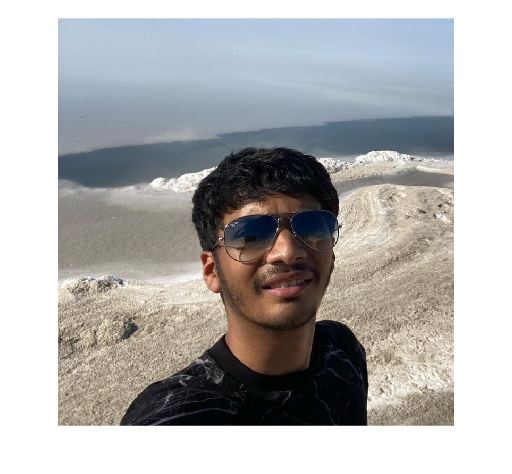

img = imread("C:\Users\snehs\Downloads\WhatsApp Image 2024-04-11 at 4.26.29 PM.jpeg");
imshow(img);

**Inference :- **Here , we learnt to read an image file from the PC and display it in Matlab .

### 2. Display the properties of this image and find its size, format, datatype.

whos img;

  Name        Size                 Bytes  Class    Attributes

  img       767x745x3            1714245  uint8              



**Inference :-** Here , we see tht 'whos' is a function which gives size , bytes , class and attributes of the image .

### 3. Convert your image into grayscale and save the same image in a new location (DO NOT USE THE FUNCTION RGB2GRAY).

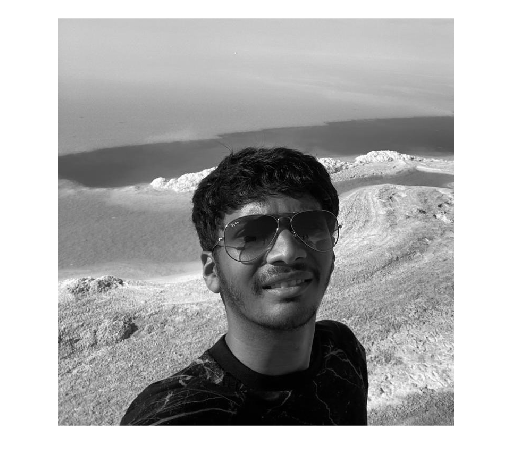

mean1 = uint8(mean(img,3));
figure(2); imshow(mean1);


%We can also convert grayscale by splitting gray into 3 planes apply Gray
%to RGB equation so that we can get back the RGB image

**Inference :-** Here , we converted an RGB image to Grayscale by taking mean of all the three planes .

### 4.Compare the original RGB image and grayscale image using sub-plot as well montage.

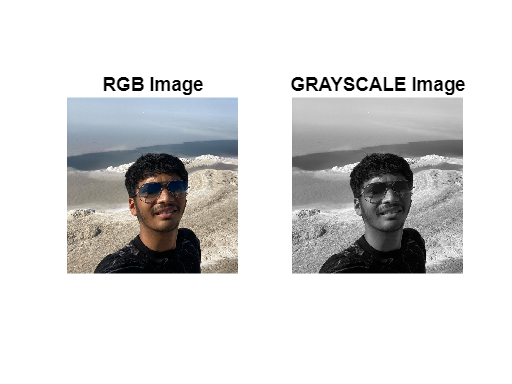

figure(3);
subplot(1,2,1);imshow(img);
subplot(1,2,2);imshow(mean1);
subplot(1,2,1);title('RGB Image');
subplot(1,2,2);title('GRAYSCALE Image');

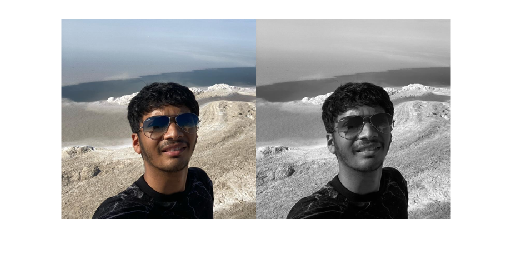

figure(4);
montage({img,mean1});

**Inference :- **Here , we learnt to plot multiple images together so that we can compare them easily by to methods i.e. subplot and montage .

### 5.Perform the following operations on your image:

### • Resize • Rotate • Zoom • Plot all of them in a single plot.

#### A) Resize : 

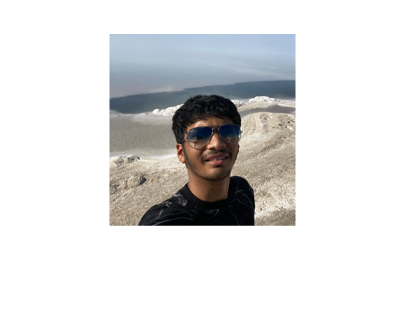

sf = 0.25;
rimg = imresize(img,sf);
imshow(rimg);

whos rimg;

  Name        Size                Bytes  Class    Attributes

  rimg      192x187x3            107712  uint8              



#### B) Rotate :

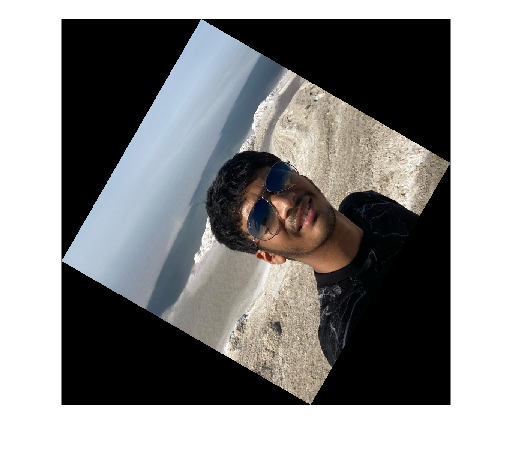

angle = 60;
roimg = imrotate(img,angle);
imshow(roimg);

whos roimg;

  Name          Size                  Bytes  Class    Attributes

  roimg      1029x1037x3            3201219  uint8              



#### C) Zoom :

zoom_factor = 2;
zimg = img ;
imshow(zimg);
whos zimg;

  Name        Size                 Bytes  Class    Attributes

  zimg      767x745x3            1714245  uint8              



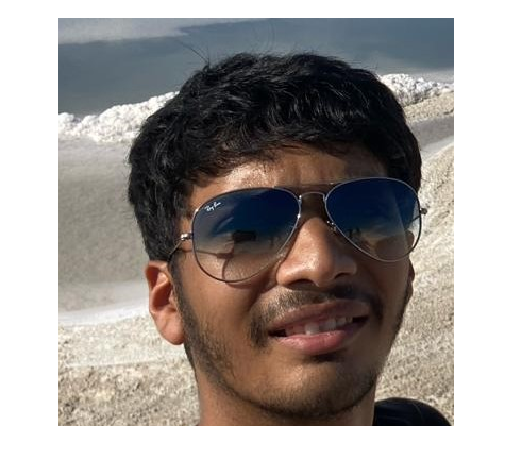


zoom on;
zoom(zoom_factor)

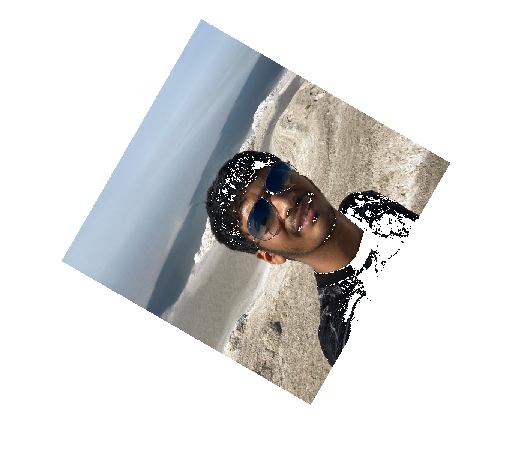

T = roimg;
mask = T(:,:,3) < 10;
T(repmat(mask, [1, 1, 3])) = 255;
imshow(T); 

#### D) Plot all of them in a single plot

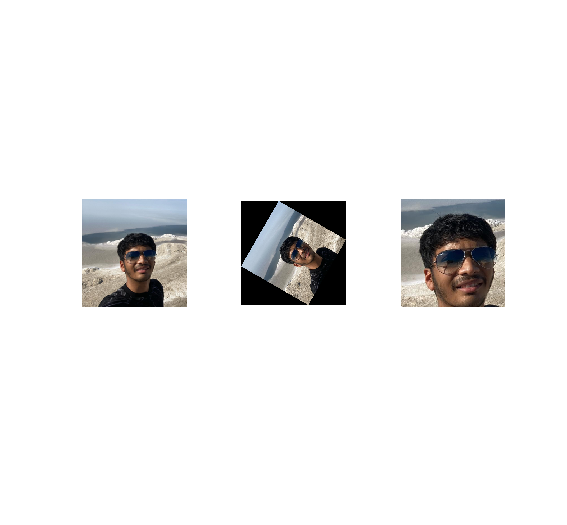

figure(6);
subplot(1,3,1);imshow(rimg);
subplot(1,3,2);imshow(roimg);
subplot(1,3,3);imshow(zimg);
zoom on ;
zoom(2)

**Inference :- **Here , we learnt ro resize an image to any specific ratio , rotate an image to any certain angle and to zoom an image to any zoom factor .

### 6. Convert the image formats:

### • Gray to binary

### • Gray to matrix

### • RGB to gray    

#### A) Gray to Binary : 

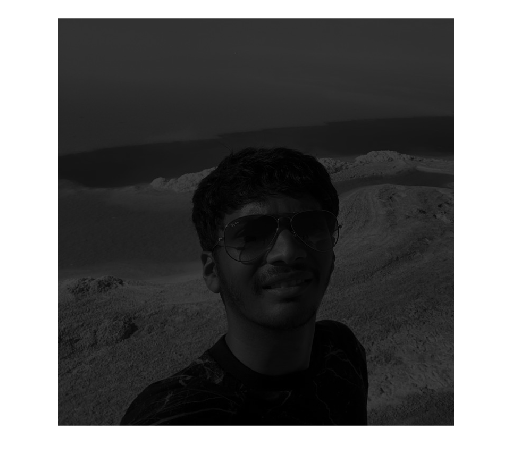

figure(7);
bimg = gray2ind(mean1);
subplot(1,1,1); 
imshow(bimg);

#### B) Gray to Matrix :

save sneh img
file = matfile('sneh.mat')

file =   matlab.io.MatFile

  Properties:
              Properties.Source: 'C:\Users\snehs\OneDrive\Desktop\Nirma Assignments\sneh.mat'
            Properties.Writable: false                                                       
    Properties.ProtectedLoading: false                                                       
                            img: [3-D uint8]                                                 

  Methods


image = file.img;
imshow(image);  

#### C) RGB to Binary :

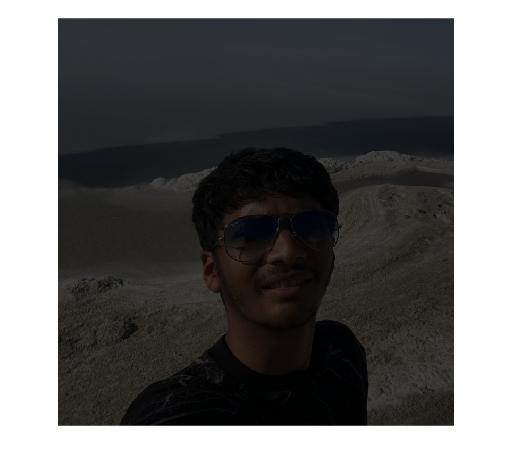

figure(8);
b1img = gray2ind(img);
subplot(1,1,1); 
imshow(b1img);

**Inference :- **Here , we explored how to convert Gray Image to Binary , Gray Image to Matrix and RGB Image to Binary .

**Conclusion :- In this experiment , we learnt about the fundamentals and basics steps for Image Processing . These steps will be very crucial for further experiments .**